%run finite_superposition.p

Exercise on convolution

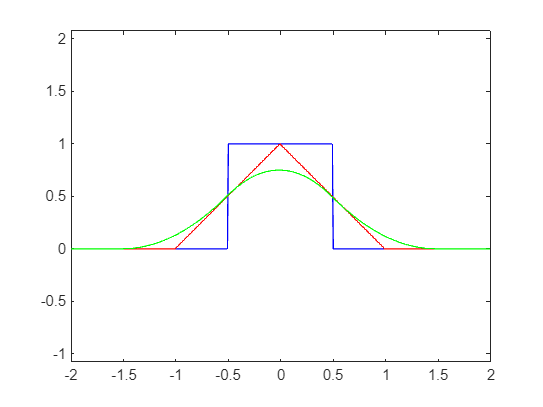

a=-2; b=2; T=b-a; t=a:.01:b; N=numel(t)-1;
R=rectpuls(t);
RR=conv(R,R,'same')*T/N; % double convolution
RRR=conv(RR,R,'same')*T/N; % triple convolution
plot(t,R,'b'); axis equal; hold on
plot(t,RR,'r')
plot(t,RRR,'g')
hold off;



%Convolution by means of Discrete Fourier Transform;
FR=fft(R)

FR = 1.0e+02 *

   1.0000 + 0.0000i  -0.9007 - 0.0141i   0.6379 + 0.0200i  -0.3023 - 0.0142i   0.0025 + 0.0002i   0.1782 + 0.0140i  -0.2119 - 0.0200i   0.1300 + 0.0143i  -0.0025 - 0.0003i  -0.0976 - 0.0139i   0.1262 + 0.0199i  -0.0827 - 0.0144i   0.0025 + 0.0005i   0.0664 + 0.0137i  -0.0891 - 0.0199i   0.0603 + 0.0145i  -0.0024 - 0.0006i  -0.0496 - 0.0135i   0.0683 + 0.0198i  -0.0472 - 0.0145i   0.0024 + 0.0008i   0.0391 + 0.0134i  -0.0548 - 0.0197i   0.0385 + 0.0145i  -0.0023 - 0.0009i  -0.0319 - 0.0132i   0.0453 + 0.0196i  -0.0323 - 0.0145i   0.0023 + 0.0011i   0.0266 + 0.0130i  -0.0382 - 0.0194i   0.0275 + 0.0145i  -0.0022 - 0.0012i  -0.0224 - 0.0128i   0.0327 + 0.0193i  -0.0238 - 0.0145i   0.0021 + 0.0014i   0.0191 + 0.0125i  -0.0281 - 0.0191i   0.0207 + 0.0145i  -0.0021 - 0.0015i  -0.0164 - 0.0123i   0.0244 + 0.0189i  -0.0181 - 0.0144i   0.0020 + 0.0016i   0.0142 + 0.0121i  -0.0212 - 0.0186i   0.0158 + 0.0144i  -0.0019 - 0.0017i  -0.0122 - 0.0118i


FRR= (FR.*FR)/N*T;
RR2=ifft(FRR);
RR2=fftshift(RR2);
RRcc= cconv(R,R,length(R))*T/N;

RRcc= fftshift(RRcc);
norm(RR2-RRcc)

ans = 2.5515e-15

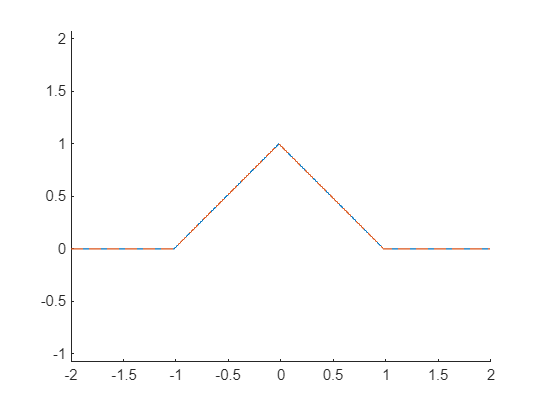


clf; figure; hold on; axis equal;
plot(t,RR2);
plot(t,RRcc,'LineStyle','--');
hold off;

a=-2; b=2; T=b-a; t=a:.01:b; N=numel(t)-1;
rng('default');
R=rand(size(t)).*rectpuls(t);
RR=conv(R,R,'same')*T/N; % double convolution
RRR=conv(RR,R,'same')*T/N; % triple convolution
plot(t,R,'b'); axis equal; hold on
plot(t,RR,'r')
plot(t,RRR,'g')

%Convolution by means of Discrete Fourier Transform;
FR=fft(R) %Compute Fourier of R

FR =   47.4329 + 0.0000i -42.8886 - 1.1584i  30.9033 + 1.7581i -15.7134 - 1.5451i   2.3518 + 0.7052i   5.4075 + 0.2430i  -6.4442 - 0.7369i   2.4402 + 0.4792i   3.2028 + 0.4047i  -7.0921 - 1.4444i   7.3717 + 2.0898i  -4.3583 - 2.0102i   0.0698 + 1.2612i   3.0181 - 0.2280i  -3.3050 - 0.6138i   0.8207 + 0.9779i   2.9251 - 0.9224i  -5.8424 + 0.7907i   6.3910 - 0.9763i  -4.3407 + 1.6509i   0.8001 - 2.6217i   2.4487 + 3.4087i  -3.9164 - 3.5069i   3.1529 + 2.6878i  -0.9026 - 1.1674i  -1.3719 - 0.4621i   2.3074 + 1.5123i  -1.3547 - 1.5437i  -0.9742 + 0.5923i   3.4221 + 0.8449i  -4.6660 - 2.0602i   3.9890 + 2.4886i  -1.6041 - 1.9786i  -1.5052 + 0.8419i   4.1054 + 0.3378i  -5.3029 - 1.0254i   4.9014 + 1.0091i  -3.3790 - 0.4843i   1.5446 - 0.0890i  -0.0920 + 0.2660i  -0.7028 + 0.1256i   1.0052 - 0.8971i  -1.1972 + 1.6209i   1.5667 - 1.8930i  -2.1059 + 1.5809i   2.5262 - 0.9171i  -2.4641 + 0.3810i   1.7402 - 0.4330i  -0.5095 + 1.2448i  -0.7868 - 2.5751i


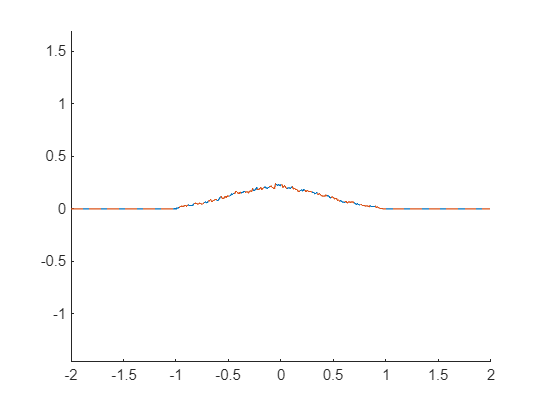

FRR= (FR.*FR)/N*T; %Apply convolution F(R).*F(R)

RR2=fftshift( ifft(FRR) ); %Apply the iDFT and fftshift
FRRR=(FRR.*FR)*T/N; %Convolution 2 times of FR
RRR3=fftshift( ifft(FRRR) );


%Convolution using cconv() function
FRRcc= cconv(R,R,length(R))*T/N; %Double convolution with cconv
FRRcc= fftshift(FRRcc); %No need to ifft()
FRRRcc =  cconv(RR,R,length(R))*T/N;
FRRRcc= fftshift( FRRRcc );

clf; figure; hold on; axis equal;
plot(t,RR2);
plot(t,FRRcc,'LineStyle','--');
hold off;


clf; figure; hold on; axis equal;
plot(t,RRR3);
plot(t,RRR,'g');
hold off;


clf; figure; hold on; axis equal;
plot(t,RRR,'g');
plot(t,FRRRcc,'LineStyle','--');
hold off;

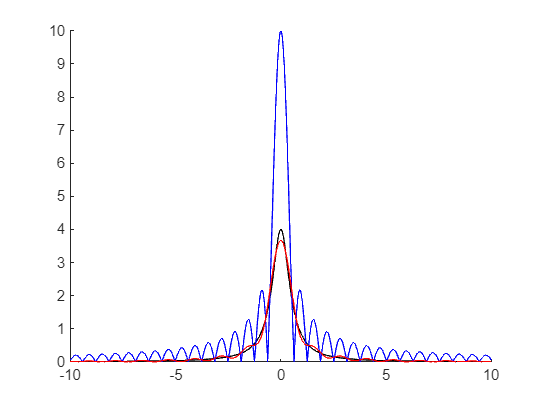

syms t real; f=exp(-abs(t)/2); 
L=10; w=rectangularPulse(-L/2, +L/2,t);

clf; figure; hold on; 
fplot(f,[-10,10]); fplot(w,[-10,10]);
fplot(f*w,[-10 10]);
hold off;

F=fourier(f,t); 
W=fourier(w,t);
G=fourier(f*w,t);

clf; figure; hold on;
fplot(abs(F),[-10,10], 'Color','k');
fplot(abs(W),[-10,10], 'Color','b');
fplot(abs(G),[-10,10], 'Color','r');
hold off;